# 中山大学电子与通信工程学院

# 《数字信号处理实验》实验报告

## 实验四 离散系统的描述模型和频率响应分析

## 一、实验目的

- 了解离散系统的基本描述模型

- 掌握各种模型相互间的关系及转换方法

- 了解离散系统的零极点与系统因果性和稳定性的关系

- 观察离散系统零极点对系统冲击响应的影响

- 加深对离散系统的频率响应特性基本概念的理解

- 了解离散系统的零极点与频响特性之间的关系

## 二、实验要求

- 每个实验内容都要清晰展示实验过程和实验结果。

- 绘图时必须明确标出各个坐标轴的意义和单位。

- 绘制多个子图时要明确标出各个子图所画的内容。

- 绘制多个信号时采用不同的线型和颜色区分、添加图例。

- 严禁抄袭、复制，发现雷同报告或代码双方成绩均作废！！

## 三、实验原理

（根据具体实验内容和要求，简述所涉及的数字信号处理基本概念、理论知识和实验原理，对基本概念和理论进行解释、列出必要的公式）

- 一个线性移不变(LSI)离散系统可以用线性常系数差分方程表示，这是系统在时域的表达式；对差分方程两边进行z变换，得到离散LSI系统的系统传递函数(tf)模型；对系统传递函数(tf)模型进行因式分解可以得到系统传递函数的零-极点增益(zpk)模型；当zpk模型中的极点均为单极点时，可以将其分解为部分分式，表示为系统的极点留数(rpk)模型；离散LSI系统函数经常包含复数的零、极点，把每一对共轭零点或共轭极点多项式合并，就可以得到二次分式(sos)模型；另外还有状态变量(ss)模型。

- 系统传递函数(tf)模型。对上式所示的线性常系数差分方程两边进行z变换，可以得到离散LSI 系统的系统传递函数：   


$$H{\left(z\right)}=\frac{Y\left(z\right)}{X\left(z\right)}=\frac{\sum_{m=0}^M b_m z^{-m} }{\sum_{k=0}^N a_k z^{-k} }=\frac{b_0 +b_1 z^{-1} +b_2 z^{-2} +\dots +b_M z^{-M} }{1+a_1 z^{-1} +a_2 z^{-2} +\dots +a_N z^{-N} }$$


          3.零--极点增益(zpk)模型。对上式表示的系统传递函数进行因式分解，可以得到系统传递函数的零-极点增益模型：

 
$$H{\left(z\right)}=k\frac{{\left(z-q_1 \right)}{\left(z-q_2 \right)}\dots \left(z-q_M \right)}{{\left(z-p_1 \right)}{\left(z-p_2 \right)}\dots \left(z-p_N \right)}$$
 

          4.二次分式(sos)模型。离散LSI系统函数经常句含复数的零、极点，把每一对共轭零点或共轭极点多项式合并，就可以得到二次分式模型：


$$H{\left(z\right)}=g\prod_{k=1}^l \frac{b_{0k} +b_{1k} z^{-1} +b_{2k} z^{-2} }{1+a_{1k} z^{-1} +a_{2k} z^{-2} }$$


          5.极点留数(rpk)模型。当零--极点增益模型中的极点均为单极点时，可以将H(z)分解为部分分式，表示为系统的极点留数模型：$H{\left(z\right)}=\frac{r_1 }{1-p_1 z^{-1} }+\frac{r_2 }{1-p_2 z^{-1} }+\dots +\frac{r_N }{1-p_N z^{-1} }+k_0$

          6.状态变量(ss)模型。系统的状态方程可表示为：

W(n+1)=AW(n)+BX(n)    

Y(n)=CW(n)+DX(n)

            表示为传递函数形式：


$$H{\left(z\right)}=\frac{Y\left(z\right)}{X\left(z\right)}=C\frac{W\left(z\right)}{X\left(z\right)}+D$$



$$=C{\left(zI-A\right)}^{-1} B+D$$


         7. 由理论分析可知，一个离散系统的因果性在时域中必须满足的充分必要条件是：

h(n)=0 n<0               

       在变换域，极点只能在z平面上一个有界的以原点为中心的圆内。如果系统函数是一个多项式，则分母上z的最高次数应大于分子上z    的最高次数。

         8.在时域中，离散系统稳定的充分必要条件是:它的冲激响应绝对可加，即：


$$\sum_{n=0}^{\infty } {\left|h{\left(n\right)}\right|}<\infty$$


        在变换域，则要求所有极点必须在z平面上以原点为中心的单位圆内

         9.综合系统的因果性和稳定性两方面的要求可知，一个因果稳定系统的充分必要条件是：系统函数的全部极点必须在z平面上以原点为中心的单位圆内。

         10.已知稳定系统传递函数的零-极点增益(zpk)模型为：


$$H{\left(z\right)}=K\frac{\prod_{m=1}^M \left(z-c_m \right)}{\prod_{n=1}^N \left(z-d_n \right)}$$


             则系统的频响函数为：


$$H{\left(e^{jw} \right)}={H{\left(z\right)}\left|\right.}_{z=e^{jw} } =K\frac{\prod_{m=1}^M {\left(e^{jw} -c_m \right)}}{\prod_{n=1}^N {\left(e^{jw} -d_n \right)}}=K\frac{\prod_{m=1}^M C_m e^{j\alpha_m } }{\prod_{n=1}^N D_n e^{j\beta_n } }={\left|H{\left(e^{jw} \right)}\right|}e^{j\varphi {\left(w\right)}}$$


             其中，系统的幅度频响特性为：


$${\left|H{\left(e^{jw} \right)}\right|}=K\frac{\prod_{m=1}^M C_m }{\prod_{n=1}^N D_n }$$


            系统的相位频响特性为：


$$\varphi {\left(w\right)}=\sum_{m=1}^M \alpha_m -\sum_{n=1}^N \beta_n +w\left(N-M\right)$$


            由公式可见，系统函数与频率响应有着密切的联系。适当地控制系统函数极点、零点的分布，可以改变离散系统的频率响应特性：

            (1)在原点(z=0)处的零点或极点至单位圆的距离始终保持不变，其值，所以对幅度响应不起作用。

            (2)单位圆附近的零点对系统幅度响应的凹谷的位置及深度有明显的影响。

            (3)单位圆内且靠近单位圆附近的极点对系统幅度响应的凸峰的位置及峰度有明显的影响。

## 四、实验所用MATLAB函数

- tf2zpk函数：将系统传递函数(tf)模型转换为系统函数的零-极点增益(zpk)模型，需要注意的是tf2zpk函数与tf2zp有细微区别，其中tf2zpk转化的系统传递函数为z变换函数，而tf2zp转化的系统传递函数为拉普拉斯变换函数。

- tf2sos函数：将tf模型转换为二次分式(sos)模型。

- tf2ss函数： 将tf模型转换为系统状态空间(ss)模型

- residuez函数： 将tf模型转换为极点留数(rpk)模型

- zplane函数： 显示离散系统的零极点分布图

- freqz函数： 求解离散时间系统的频率响应函数，其中如果没有返回值直接调用freqz函数，会直接绘制幅频和相频特性曲线，如果给定返回值则会返回频率和频率对应的幅度值。

- angle函数： 求相角

- grid函数： 在指定的图形坐标上绘制分格线

- impz函数：求解数字系统的冲激响应

- grpdelay函数：求解系统函数的群延迟，一般调用 [gd，w] = grpdelay(b，a) 返回由输入向量b和a指定的离散时间滤波器的群延迟响应gd

- zp2tf函数：与tf2zpk函数相反，将系统函数的零-极点增益(zpk)模型转换为系统传递函数(tf)模型

- prod函数：连乘

## 五、实验内容、方法、代码与结果

### **题目1**：编写MATLAB程序，已知离散时间系统的传递函数(tf)模型$\mathbf{H}\left(\mathbf{z}\right)=\frac{2+3{\mathbf{z}}^{-1} }{1+0\ldotp 4{\mathbf{z}}^{-1} +{\mathbf{z}}^{-2} }$，将其转换为：

**①**`零`**-**`极点增益`**(zpk)**`模型；`

**②**`二次分式`**(sos)**`模型；`

**③**`极点留数`**(rpk)**`模型；`

**④**`状态变量`**(ss)**`模型。`

**解答1**：

clc;
clear;
b=[2 3 0];
a=[1 0.4 1];
syms z

[zt,p,k]=tf2zpk(b,a);
zpk=k*prod(z-zt)/prod(z-p)

$$zpk = \frac{2\,z\,\left(z+\frac{3}{2}\right)}{\left(z+\frac{1}{5}-\frac{2\,\sqrt{6}\,\mathrm{i}}{5}\right)\,\left(z+\frac{1}{5}+\frac{2\,\sqrt{6}\,\mathrm{i}}{5}\right)}$$


[sos,g]=tf2sos(b,a);
sos=g*sum([1 z^-1 z^-2].*sos(1:3))/sum([1 z^-1 z^-2].*sos(4:6))

$$sos = \frac{\frac{3}{z}+2}{\frac{2}{5\,z}+\frac{1}{z^{2}}+1}$$

[r,p,k]=residuez(b,a);
rpk=r(1)/(1-p(1)/z)+r(2)/(1-p(2)/z)+k

$$rpk = \frac{-1+\frac{13\,\sqrt{6}\,\mathrm{i}}{24}}{\frac{-\frac{1}{5}+\frac{2\,\sqrt{6}\,\mathrm{i}}{5}}{z}-1}+\frac{1+\frac{13\,\sqrt{6}\,\mathrm{i}}{24}}{\frac{\frac{1}{5}+\frac{2\,\sqrt{6}\,\mathrm{i}}{5}}{z}+1}$$

[A,B,C,D]=tf2ss(b,a);
I=eye(2);
ss=C/(z*I-A)*B+D

$$ss = \frac{11\,z-10}{5\,z^{2}+2\,z+5}+2$$

### **题目2**：已知系统的零-极点增益模型分别为：

### 
$$\begin{array}{c}
{\textrm{H}}_1 \left(\mathit{\mathbf{z}}\right)=\frac{\mathit{\mathbf{z}}-0.3}{{\left(\mathit{\mathbf{z}}+0.5-0.7\mathit{\mathbf{j}}\right)\left(\mathit{\mathbf{z}}+0.5+0.7\mathit{\mathbf{j}}\right)}}\\
{\textrm{H}}_2 \left(\mathit{\mathbf{z}}\right)=\frac{\mathit{\mathbf{z}}-0.3}{{\left(\mathit{\mathbf{z}}+0.6-0.8\mathit{\mathbf{j}}\right)\left(\mathit{\mathbf{z}}+0.6+0.8\mathit{\mathbf{j}}\right)}}\\
{\textrm{H}}_3 \left(\mathit{\mathbf{z}}\right)=\frac{\mathit{\mathbf{z}}-0.3}{{\left(\mathit{\mathbf{z}}+1-\mathit{\mathbf{j}}\right)\left(\mathit{\mathbf{z}}+1+\mathit{\mathbf{j}}\right)}}
\end{array}$$


### 求这些系统的零极点分布图以及系统的冲激响应，并判断系统的因果稳定性。

**解答2**：

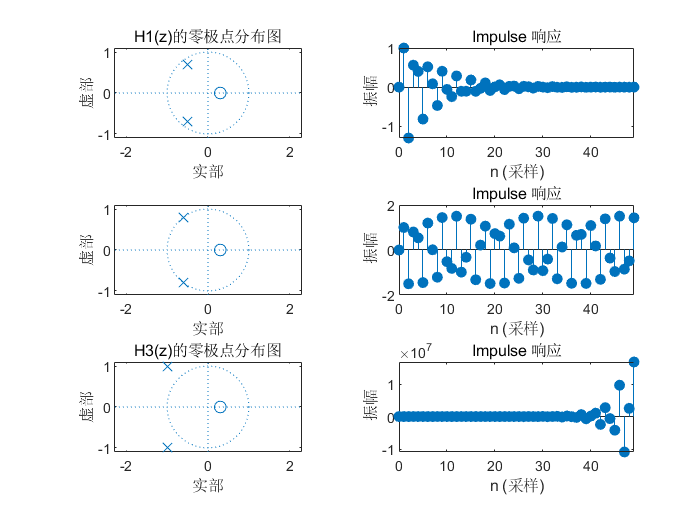

clc;
clear;
figure();
z1=0.3;
p1=[-0.5+0.7j,-0.5-0.7j];
k1=1;
[b1,a1]=zp2tf(z1,p1,k1);
subplot(3,2,1);
zplane(b1,a1);
title('H1(z)的零极点分布图');
subplot(3,2,2);
impz(b1,a1,50);

z2=0.3;
p2=[-0.6+0.8j,-0.6-0.8j];
k2=1;
[b2,a2]=zp2tf(z2,p2,k2);
subplot(3,2,3);
title('H2(z)的零极点分布图');
zplane(b2,a2);
subplot(3,2,4);
impz(b2,a2,50);

z3=0.3;
p3=[-1+1j,-1-1j];
k3=1;
[b3,a3]=zp2tf(z3,p3,k3);
subplot(3,2,5);
zplane(b3,a3);
title('H3(z)的零极点分布图');
subplot(3,2,6);
impz(b3,a3,50);

%   三个系统的零点都在Z的左半平面
%   H1(z)的两个极点处于单位圆内，是因果稳定系统，系统的冲激响应曲线随着频率的增大而收敛
%   H2(z)的两个极点处于单位圆上，不是因果稳定系统，系统的冲激响应曲线为等幅振荡
%   H3(z)的两个极点处于单位圆内，不是因果稳定系统，系统的冲激响应曲线随着频率的增大而发散
%   结论：系统只有极点处于单位圆内才是稳定的


### **题目3**：已知离散时间系统的传递函数为：$\textrm{H}\left(\mathit{\mathbf{z}}\right)=\frac{2+3{\mathit{\mathbf{z}}}^{-1} }{1+0.4{\mathit{\mathbf{z}}}^{-1} +{\mathit{\mathbf{z}}}^{-2} }$，求该系统在$0-\pi$频率范围内的相对幅度频率响应与相位频率响应曲线。

**解答3**：

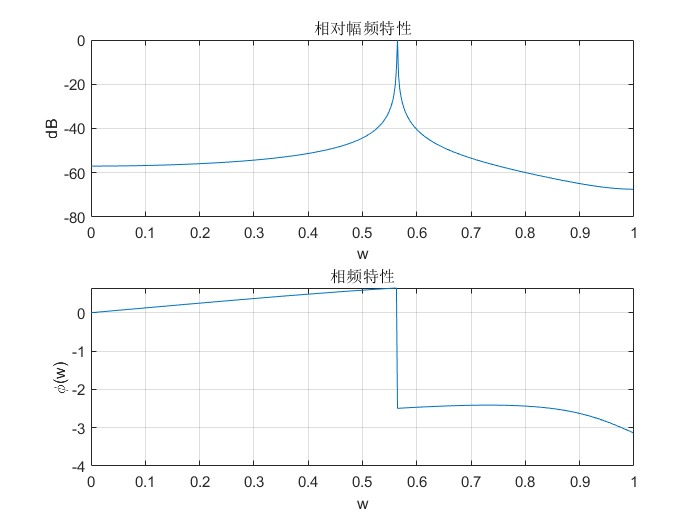

clc;
clear;
figure();
b=[2 3 0];
a=[1 0.4 1];
[h,w]=freqz(b,a);
db=20*log10(abs(h)/max(abs(h)));
subplot(2,1,1);
plot(w/pi,db);
title('相对幅频特性');
xlabel('w');
ylabel('dB');
grid on
subplot(2,1,2);
plot(w/pi,angle(h));
title('相频特性');
xlabel('w');
ylabel('\phi(w)');
grid on

### **题目4**：已知离散时间系统的零-极点增益模型为：$\mathit{\mathbf{H}}\left(\mathit{\mathbf{z}}\right)=\frac{{\left(\mathit{\mathbf{z}}\left(\mathit{\mathbf{z}}+2\right.\right)}}{{\left(\mathit{\mathbf{z}}-0.3\right)\left(\mathit{\mathbf{z}}-0.4\right)\left(\mathit{\mathbf{z}}-0.6\right)}}$，求该系统在 $0-\pi$ 频率范围内的绝对幅度频率响应、相对幅度频率响应、相位频率响应曲线以及零极点分布图。

**解答4**：

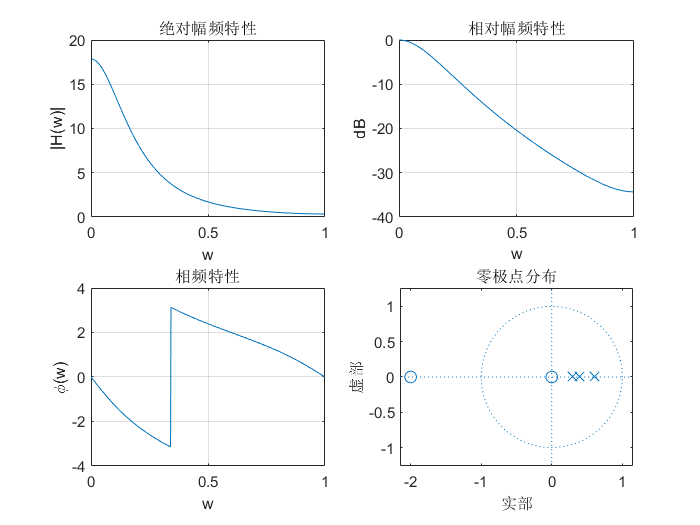

clc;
clear;
figure();

z=[0 -2]';
p=[0.3 0.4 0.6];
k=1;
[b,a]=zp2tf(z,p,k);
[h,w]=freqz(b,a);
db=20*log10(abs(h)/max(abs(h)));
subplot(2,2,1);
plot(w/pi,abs(h));
title('绝对幅频特性');
xlabel('w');
ylabel('|H(w)|');
grid on
subplot(2,2,2);
plot(w/pi,db);
title('相对幅频特性');
xlabel('w');
ylabel('dB');
grid on
subplot(2,2,3);
plot(w/pi,angle(h));
title('相频特性');
xlabel('w');
ylabel('\phi(w)');
grid on
subplot(2,2,4);
zplane(b,a);
title('零极点分布');

### **题目5**：已知离散时间系统的系统函数为$H(z)=\frac{0\ldotp 187632-0\ldotp 241242z^{-2} +0\ldotp 241242z^{-4} -0\ldotp 187632z^{-6} }{1+0\ldotp 602012z^{-2} +0\ldotp 495684z^{-4} -0\ldotp 035924z^{-6} }$，求该系统在 $0-\pi$ 频率范围内的绝对幅度频率响应、相对幅度频率响应、相位频率响应及群延迟。

**解答5**：

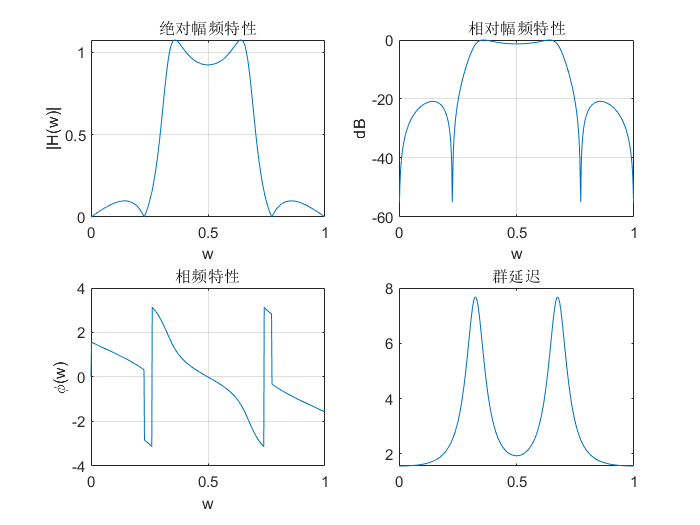

clc;
clear;
figure();
b=[0.187632 0 -0.241242 0 0.241242 0 -0.187632];
a=[1 0 0.602012 0 0.495684 0 -0.035924];
[h,w]=freqz(b,a);
db=20*log10(abs(h)/max(abs(h)));
delay=grpdelay(b,a,w);
subplot(2,2,1);
plot(w/pi,abs(h));
title('绝对幅频特性');
xlabel('w');
ylabel('|H(w)|');
grid on
subplot(2,2,2);
plot(w/pi,db);
title('相对幅频特性');
xlabel('w');
ylabel('dB');
grid on
subplot(2,2,3);
plot(w/pi,angle(h));
title('相频特性');
xlabel('w');
ylabel('\phi(w)');
grid on
subplot(2,2,4);
plot(w/pi,delay);
title('群延迟');